ntFile = 'C:\Users\ZPYin\Documents\Data\wxzk_fog_measurements\RawData\QingDao\2023\12\27\H_SCAN15_135_2_20231227055815\WX20231227055840.VIS';
dtFile = 'C:\Users\ZPYin\Documents\Data\wxzk_fog_measurements\RawData\QingDao\2023\12\27\H_SCAN15_135_2_20231227084250\WX20231227084314.VIS';

ntData = readVIS(ntFile);
dtData = readVIS(dtFile);

显示信号

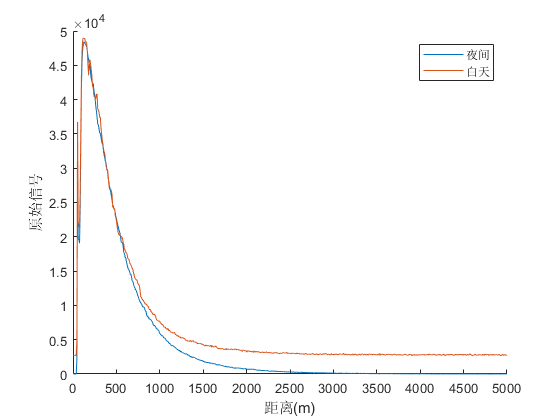

figure;

hold on;
plot((1:ntData.nBins) * ntData.hRes, squeeze(ntData.rawSignal(1,1,:)), 'DisplayName', '夜间');
plot((1:dtData.nBins) * ntData.hRes, squeeze(dtData.rawSignal(1,1,:)), 'DisplayName', '白天');

hold off;

xlabel('距离(m)');
ylabel('原始信号');

xlim([0, 5000]);

legend('Location', 'NorthEast');

信号

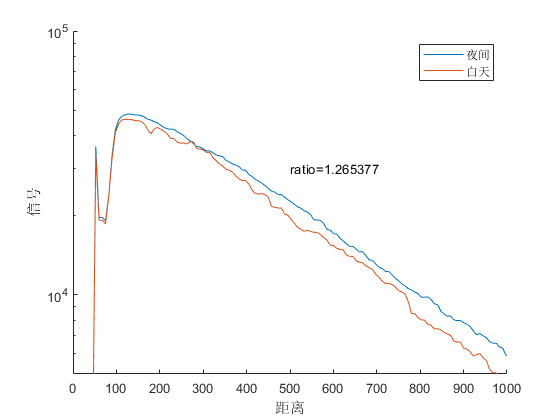

ntBg = nanmean(ntData.rawSignal(1,1,(end-100):(end-50)));
ntSignal = squeeze(ntData.rawSignal(1,1,:) - ntBg);
dtBg = nanmean(dtData.rawSignal(1,1,(end-100):(end-50)));
dtSignal = squeeze(dtData.rawSignal(1,1,:) - dtBg);
height = (1:ntData.nBins) * ntData.hRes;

figure;
hold on;

plot(height, ntSignal, 'Displayname', '夜间');
plot(height, dtSignal, 'DisplayName', '白天');


hold off;

xlabel('距离');
ylabel('信号');

xlim([0, 1000]);
ylim([5e3, 1e5]);

set(gca, 'YScale', 'log');
legend('Location', 'Northeast');

text(0.5, 0.6, sprintf('ratio=%f', nansum(ntSignal(142:242))/nansum(dtSignal(142:242))),'units','normalized');